AChmut_datapath=["/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001"
                 ]

AChmut_datapath = 5×1 string array
    "/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001"



ExperimentNames=["20220422_112_AChmtut_SW_001",
                 "20220206_112_8_AChMut_SW_001",
                 "20220425_109_AChmut_SW_001",
                 "20220207_109_AChMut_SW_001",
                 "20220712_PM29_111_Achmut_001"
                 ]

ExperimentNames = 5×1 string array
    "20220422_112_AChmtut_SW_001"
    "20220206_112_8_AChMut_SW_001"
    "20220425_109_AChmut_SW_001"
    "20220207_109_AChMut_SW_001"
    "20220712_PM29_111_Achmut_001"



All_data_path = '/Volumes/PcSSDA/AChMut/'

All_data_path = '/Volumes/PcSSDA/AChMut/'

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


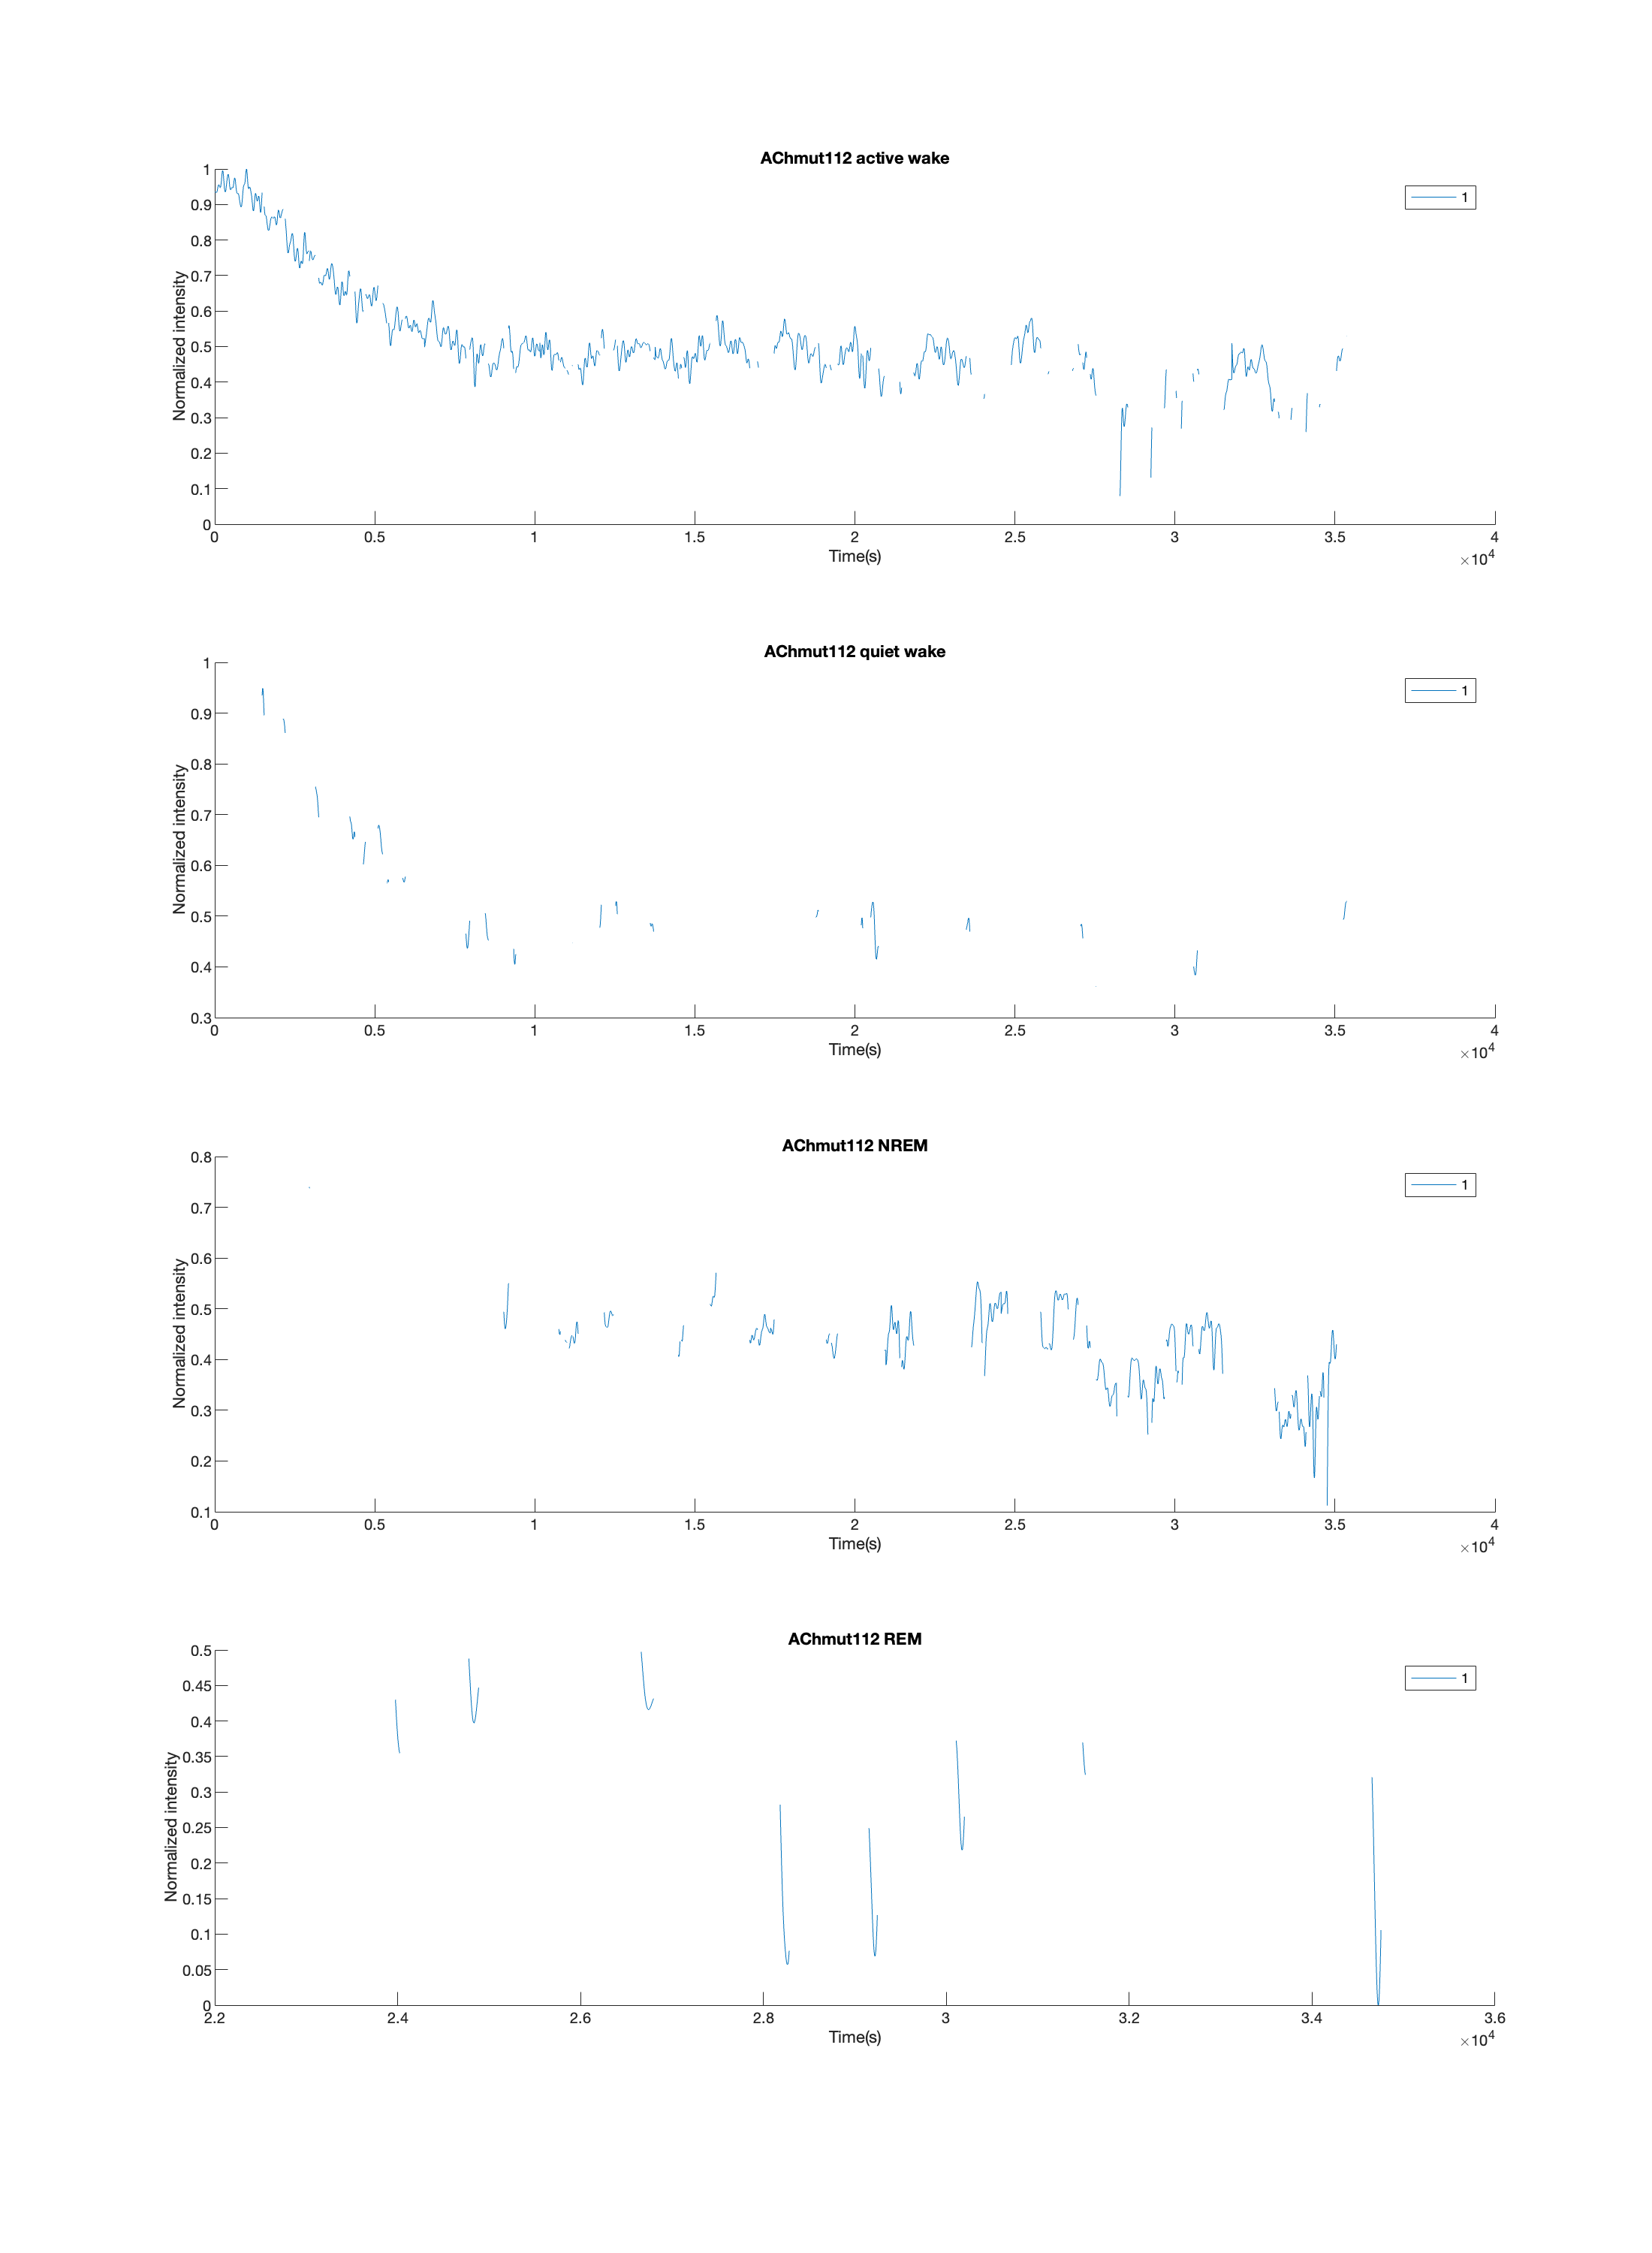

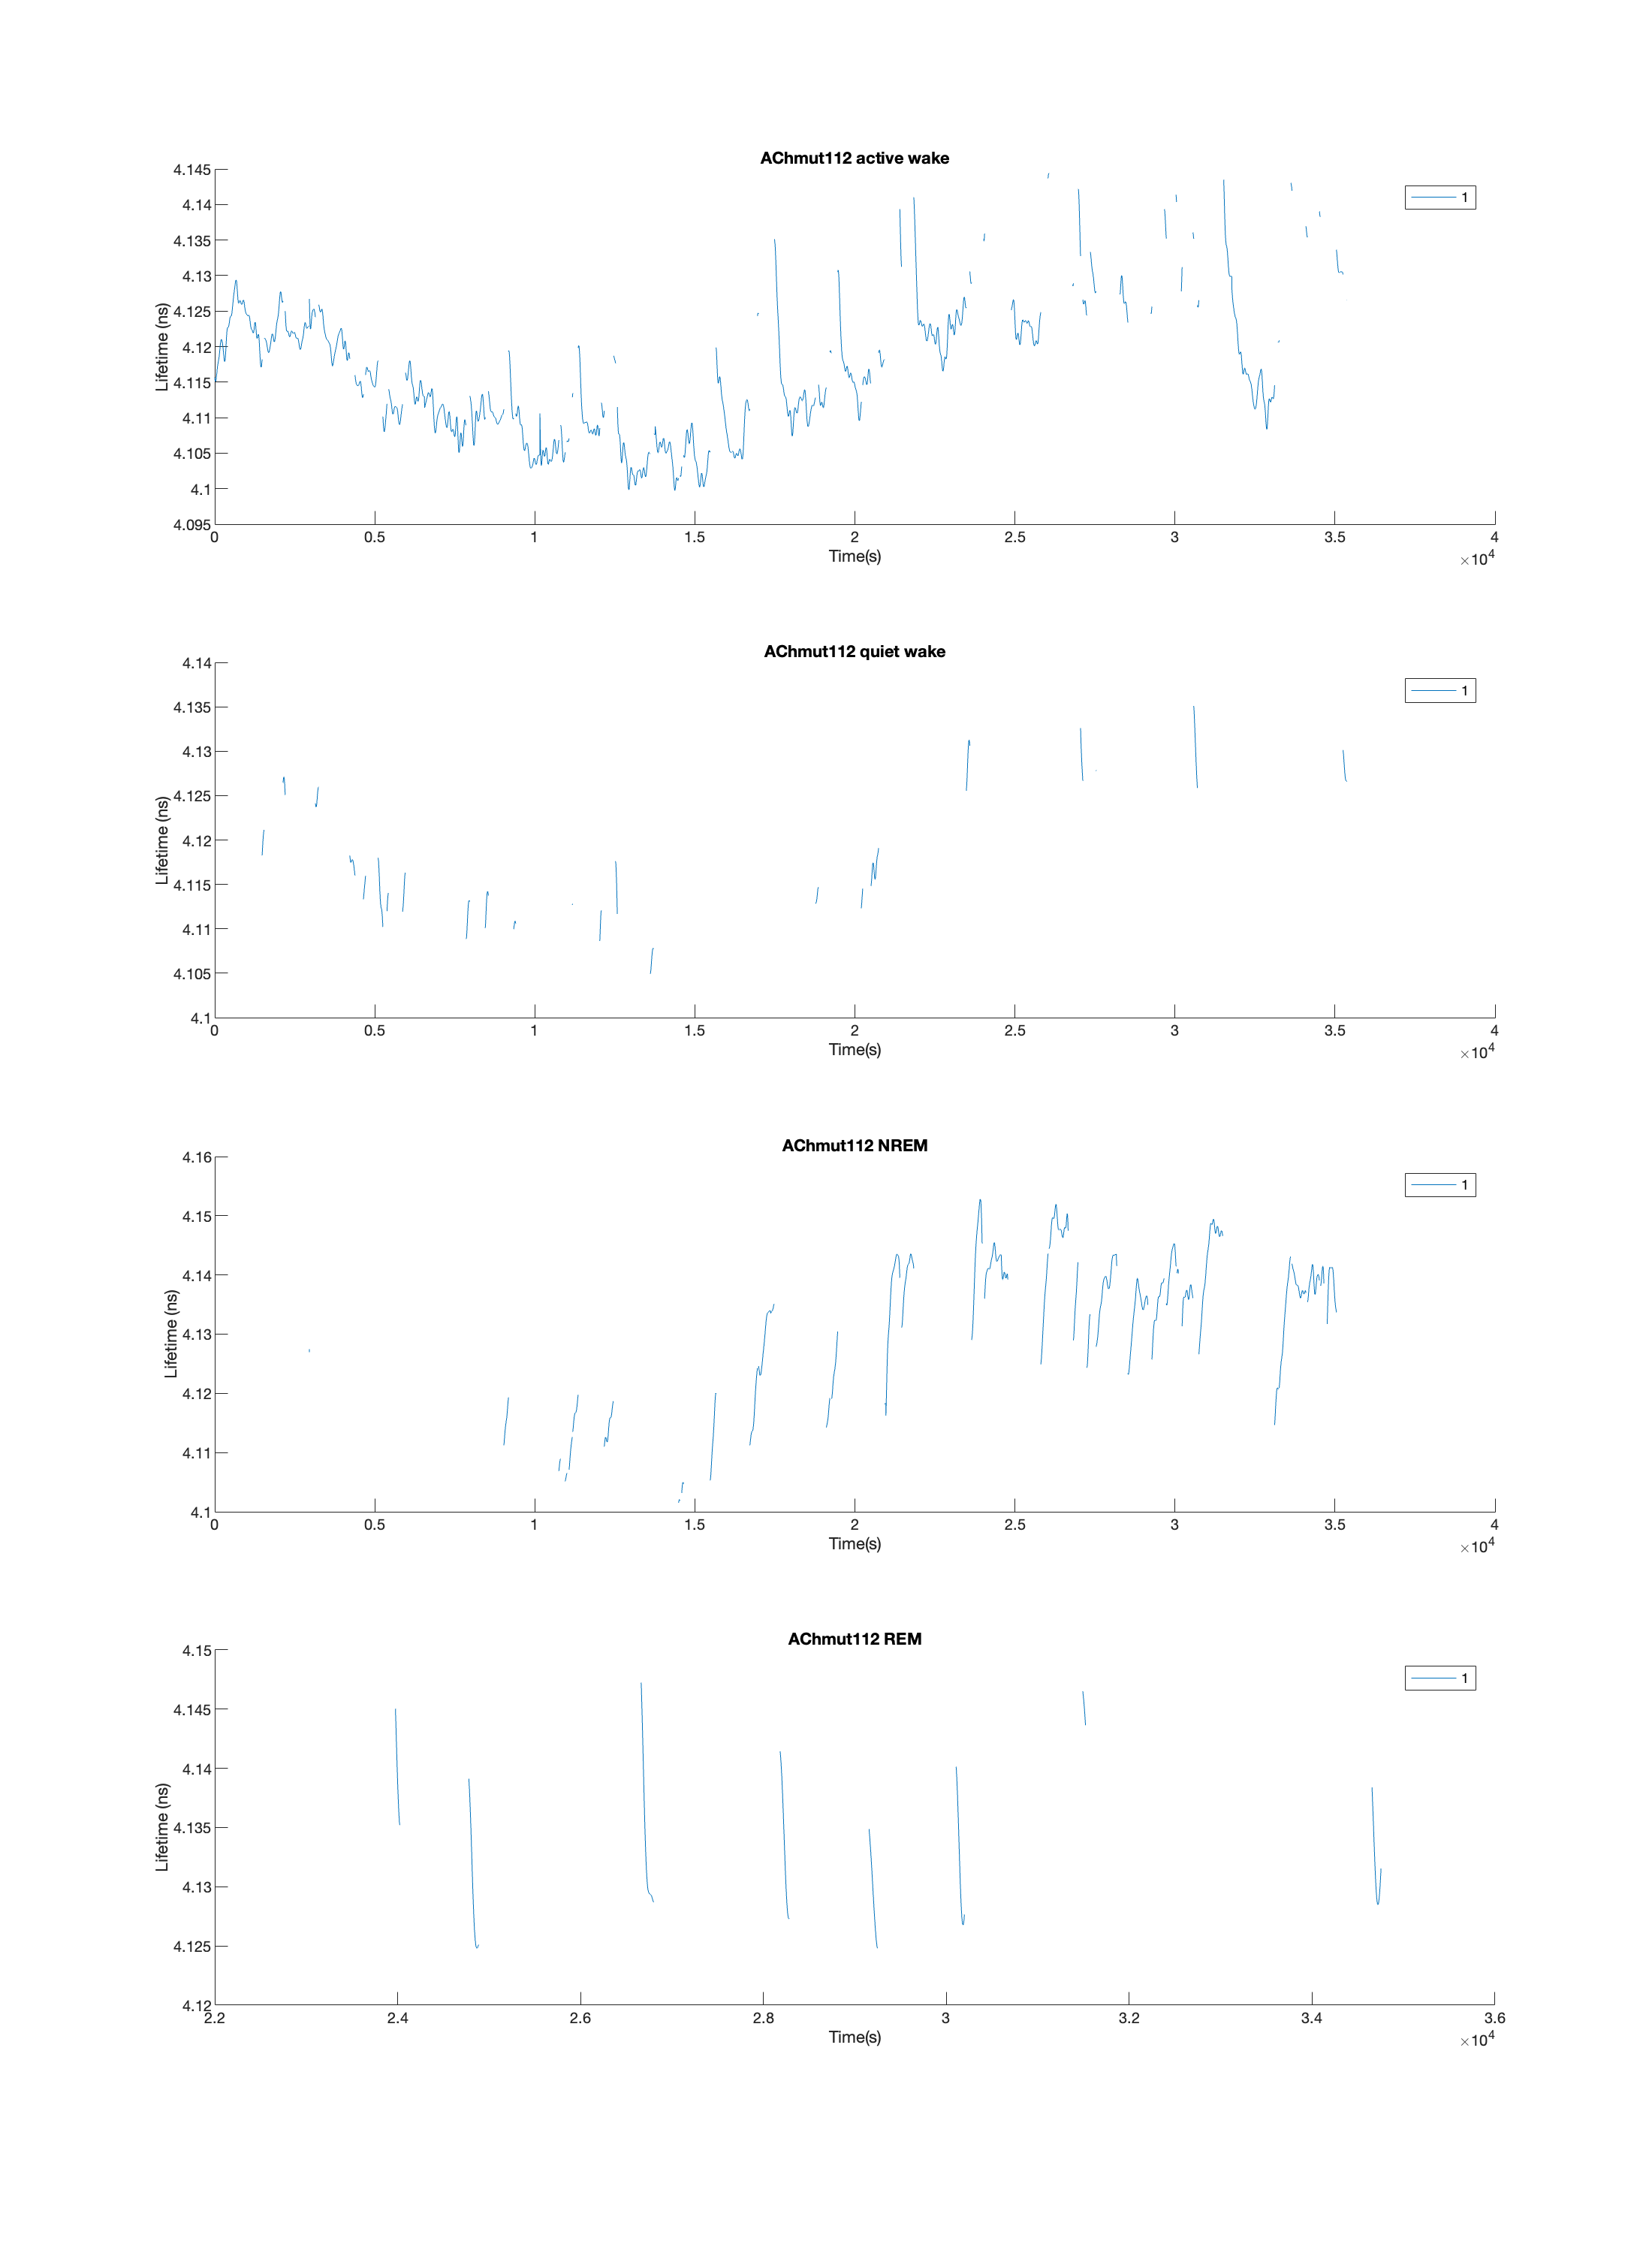

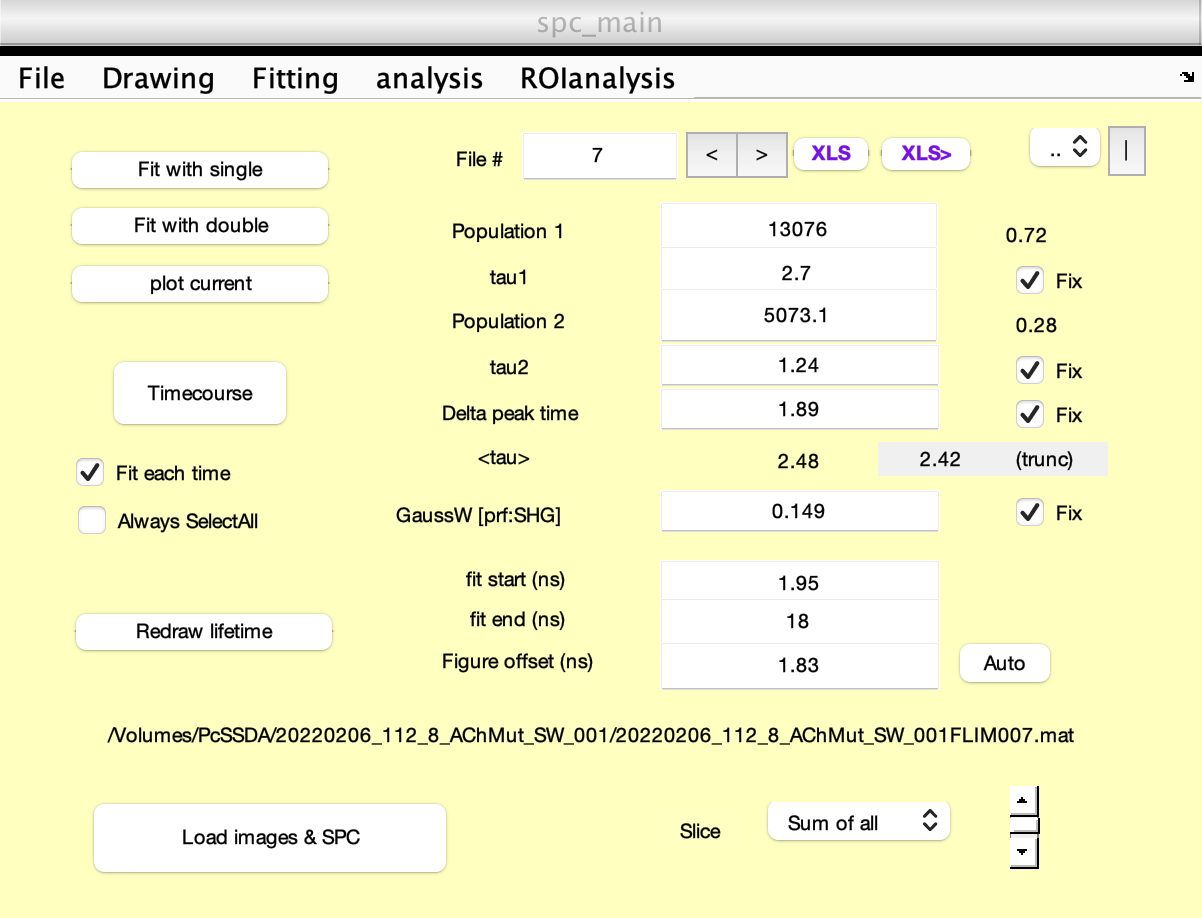

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


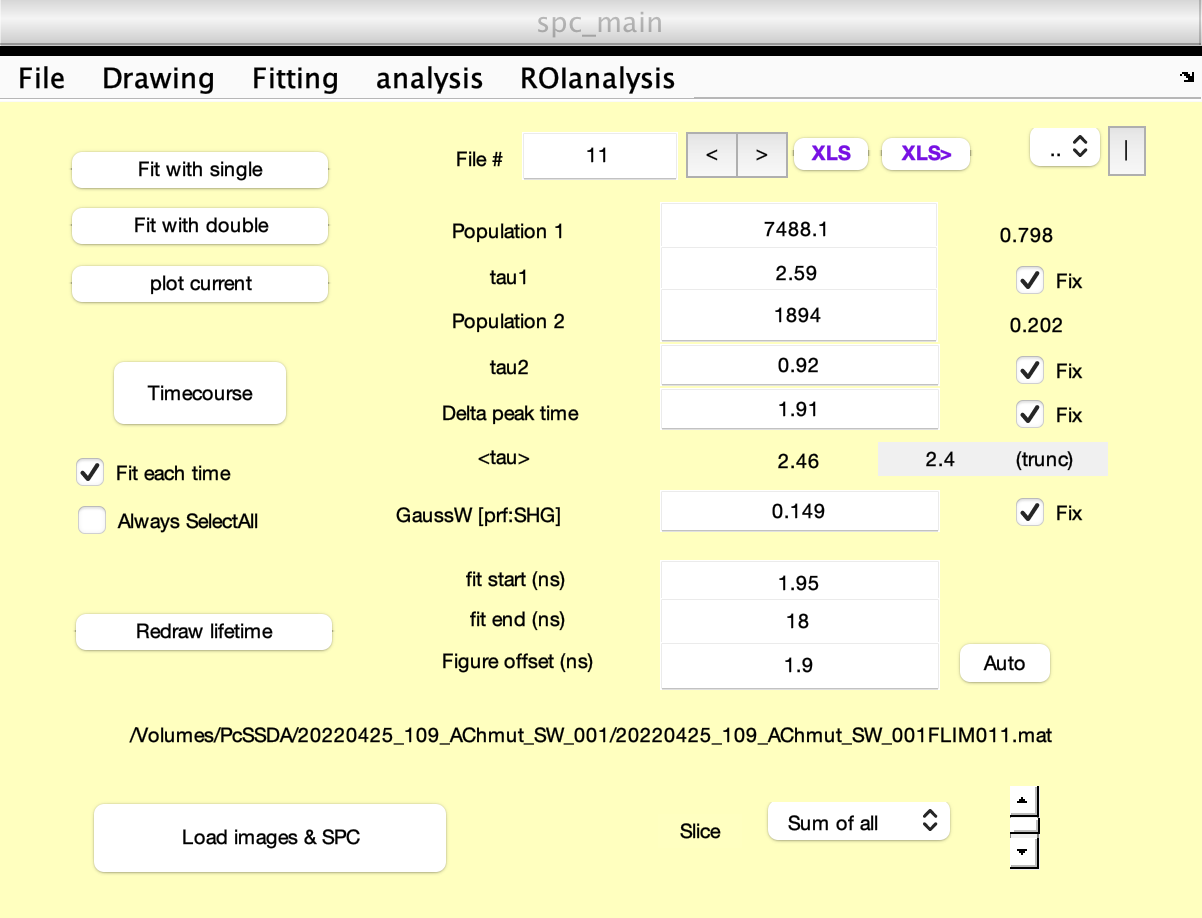

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


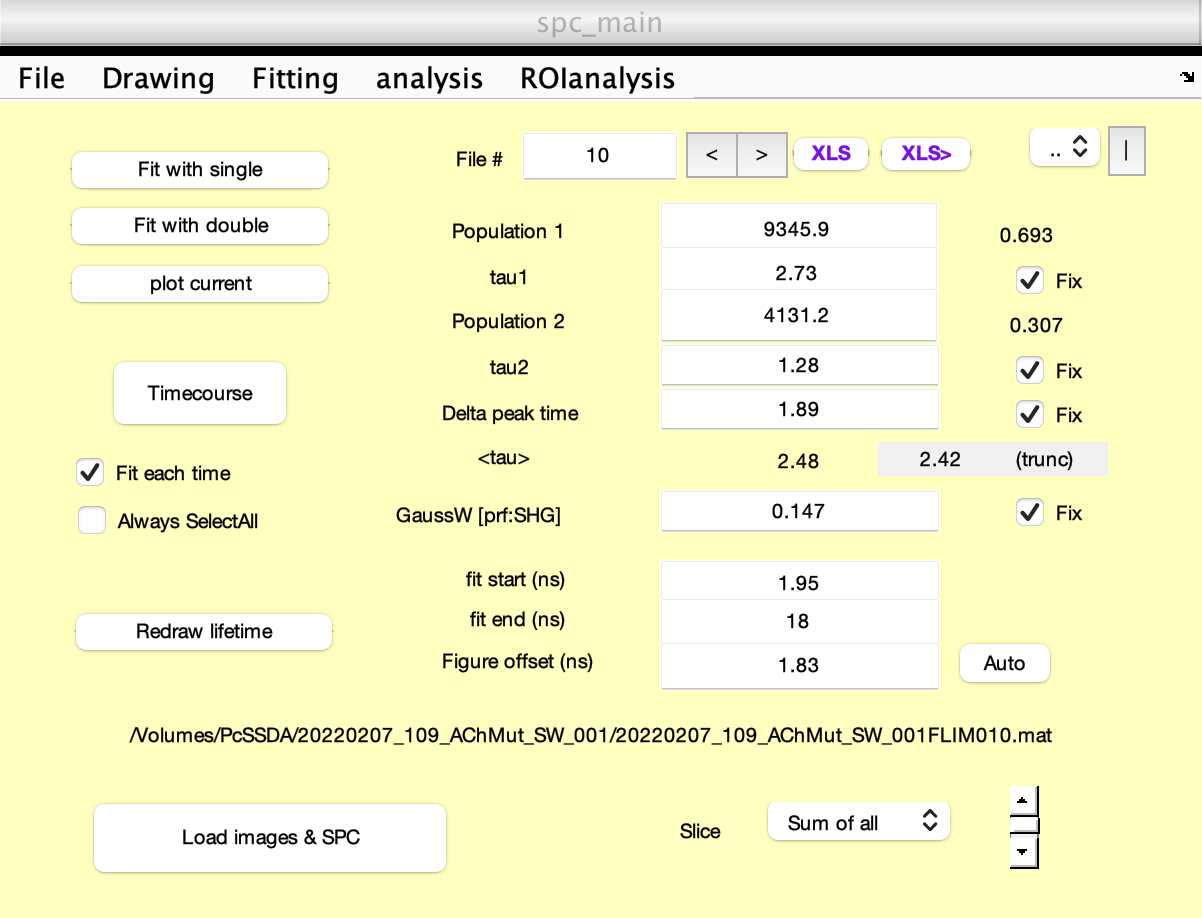

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


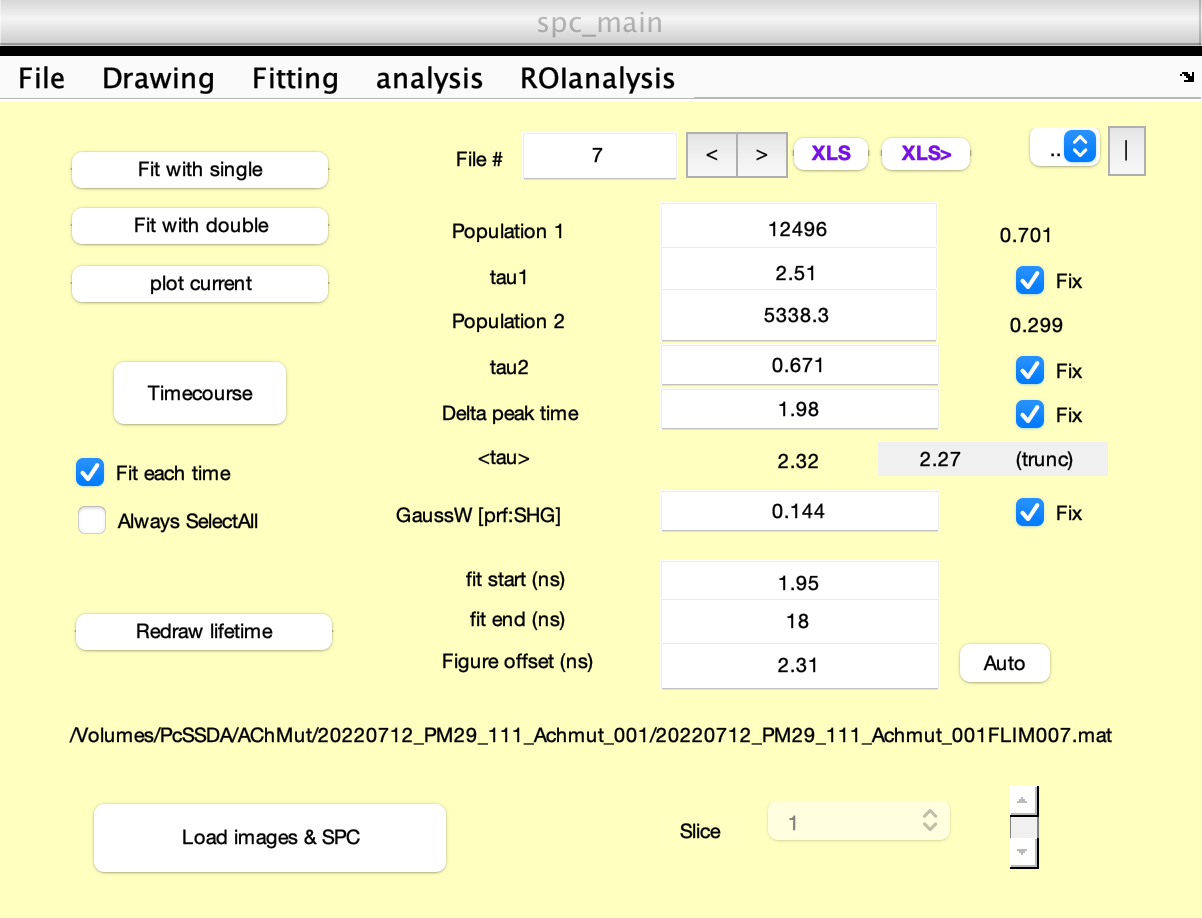

figure
for ii=1:5
    cd(convertStringsToChars(AChmut_datapath(ii)))
    load('FLP_analysis.mat');

    subplot(3,2,ii)
    yyaxis left
    plot(intensity_all_darkonly)
    ylabel('intensity')
    yyaxis right
    plot(tau_empTrunc_all_darkonly)
    ylabel('Lifetime(ns)')
    legend('Intensity','Lifetime')
    title(ExperimentNames(ii))

end

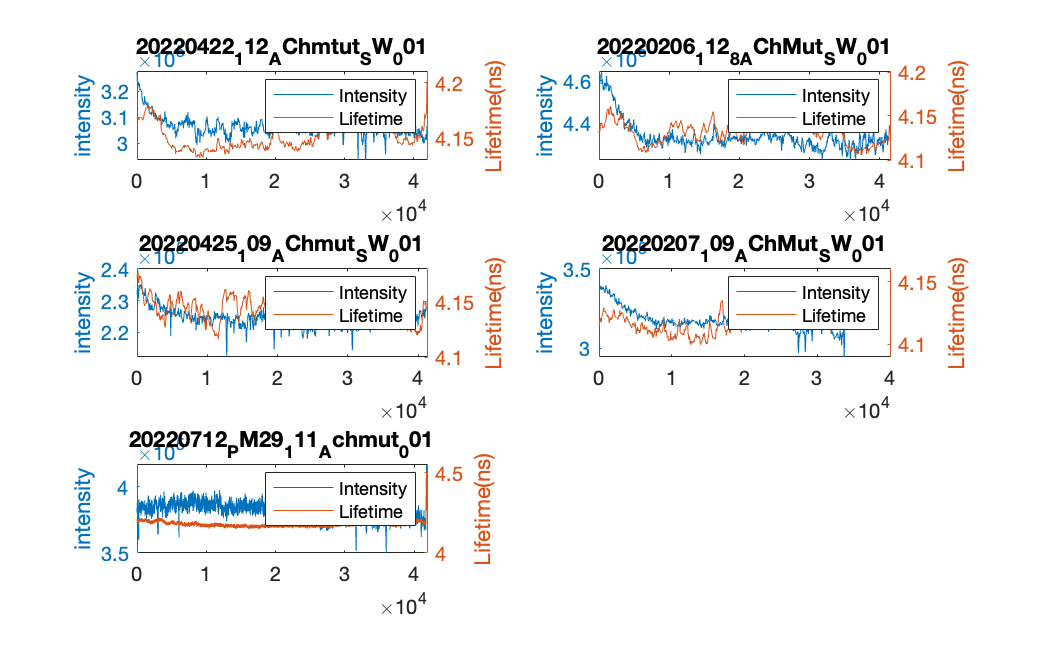

set(gcf, 'Position', get(0, 'Screensize'));
saveas(gcf,[All_data_path,'Intensity_lifetime_drifting.fig'])
saveas(gcf,[All_data_path,'Intensity_lifetime_drifting.png'])

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


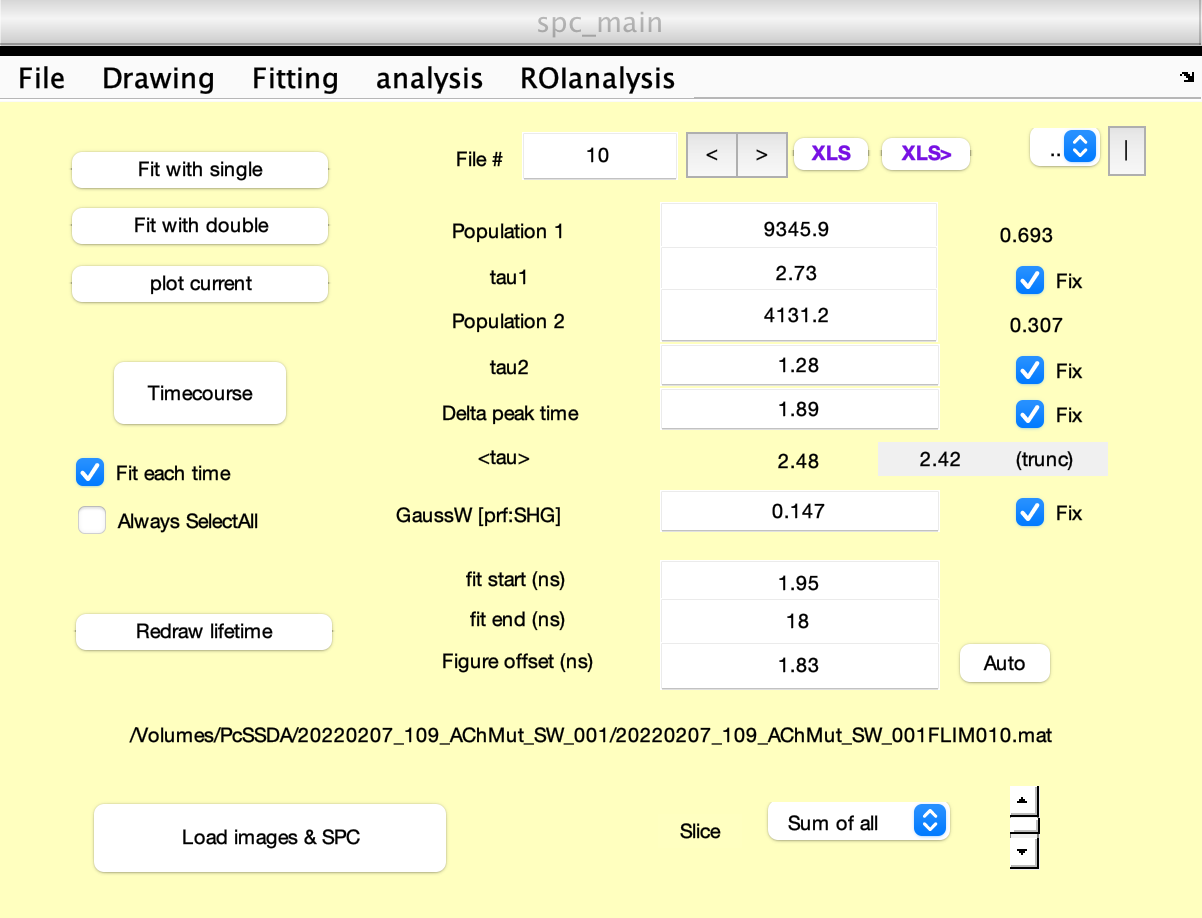

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


figure
for ii=1:5
    cd(convertStringsToChars(AChmut_datapath(ii)))
    load('FLP_analysis.mat');
    lifetime_histograms_all_darkonly = lifetime_histograms_all(:,dark_acqs);
    maxs=max(lifetime_histograms_all(:,dark_acqs));
    histograms_norm = lifetime_histograms_all_darkonly./maxs;
    semilogy(mean(transpose(histograms_norm)))
    hold on
end

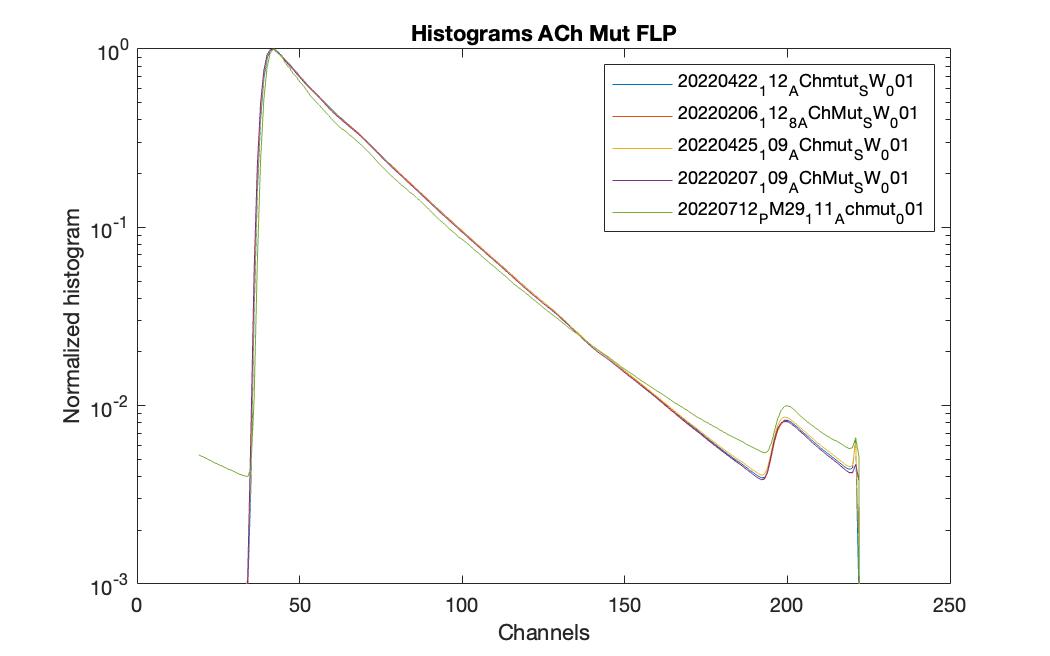


ylim([10e-4,1])
ylabel('Normalized histogram')
xlabel('Channels')
legend(ExperimentNames)
title('Histograms ACh Mut FLP')
set(gcf, 'Position', get(0, 'Screensize'));
saveas(gcf,[All_data_path,'Histograms.fig'])
saveas(gcf,[All_data_path,'Histograms.png'])
hold off